costovariabile=6.1;
prezzounitario=19;
costofisso=2700;


% imposto il costo fisso nella retta gialla
x= linspace(0,400);
y= costofisso*ones(size(x));
figure
plot(x,y, 'Color','y')
xlim([0 400])
xlabel('Unità vendute')
ylabel('Costi-Vendite-Profitti')

hold on
% imposto il costo variabile
z=costovariabile*x+costofisso; % plotto il costo totale nella retta blu
plot(x,z,'b')

% imposto il ricavo unitario
k=prezzounitario*x; % plotto i ricavi totali nella retta rossa
plot(x,k, 'r')

% trovo dove i ricavi totali sono uguali ai costi totali
A=[1 -costovariabile; 1 -prezzounitario];
b=[costofisso;0];
breakeven=A\b;
scatter(breakeven(2,1), breakeven(1,1), LineWidth=10)

% mostro breakeven point oppure il messaggio di errore se breakeven non è nell'intervallo
if breakeven(2,1)<=400 && breakeven(2,1)>=0
    disp('----------------------------------')
    disp('Unità da vendere Breakeven point:')
    disp(breakeven(2,1))
    disp('----------------------------------')
else
    disp('non è possibile trovare il punto di break even nell intervallo di cui sopra')
end

----------------------------------


Unità da vendere Breakeven point:


  209.3023



----------------------------------


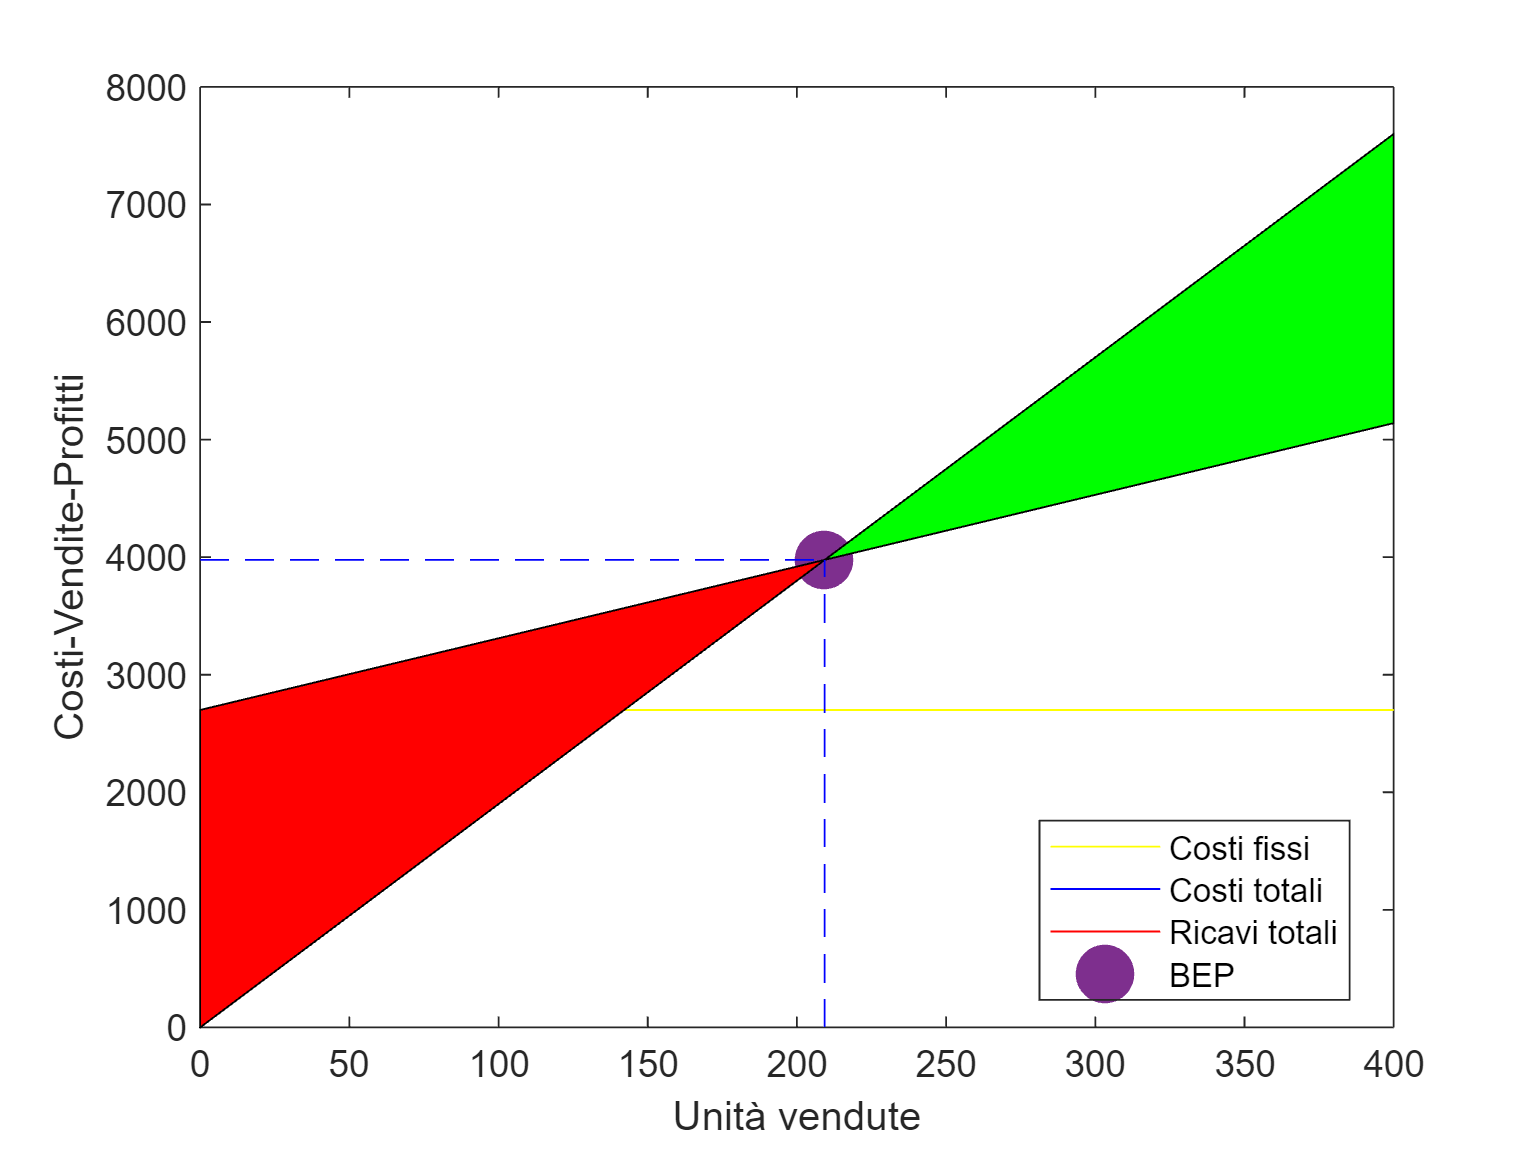


% coloro di rosso l'area di perdita e di verde l'area di guadagno
checkboxA=true;
if checkboxA==true
    fill([0 0 breakeven(2,1)], [0, costofisso, breakeven(1,1)], 'r') 
    fill([breakeven(2,1) 400 400], [breakeven(1,1), ((costovariabile*400)+(costofisso)), (prezzounitario*400)], 'g') 
end
% traccio le coordinate del breakeven
checkboxB=true;
if checkboxB==true
    br1x=[breakeven(2,1),breakeven(2,1)];
    br1y=[0,breakeven(1,1)];
    plot(br1x, br1y, 'Color','b', 'LineStyle','--')

    br2x=[0,breakeven(2,1)];
    br2y=[breakeven(1,1),breakeven(1,1) ];
    plot(br2x,br2y, 'Color','b','LineStyle','--')
end
legend('Costi fissi','Costi totali','Ricavi totali','BEP','Location','best')